## Datos

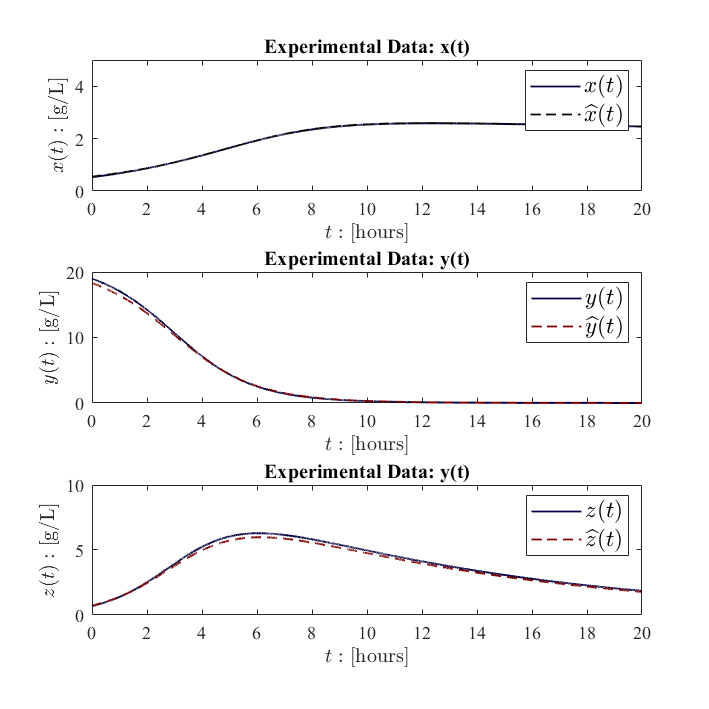

% Ejemplo de parámetros P 
p1 = 289.385E-3; p2 = 2.281; p3 = 1.066E-3; p4 = 7.25E-3; 
p5 = 56.893E-3; p6 = 71.842E-3; p7 = 824.233E-9; p8 = 19.088E-3;
p9 = 46.352E-3; p10 =149.899E-3; 

P = [p1, p2, p3, p4, p5, p6, p7, p8, p9, p10];

%Valores de tiempo
t0 = 0; tend = 20; %t0 = 0; tend = length(x)-1;
dt = 1E-3;
t = t0:dt:tend; %t = t0:dt:tend*dt;

% Ganancias 
L1 = 2;
L2 = 1.5;
L3 = 0.4;

% Llamar a la función

[x,y,z,xe,ye,ze] = Observer_KM(P,tend,dt,L1,L2,L3);

plotData2(t, x, y, z, xe, ye, ze);

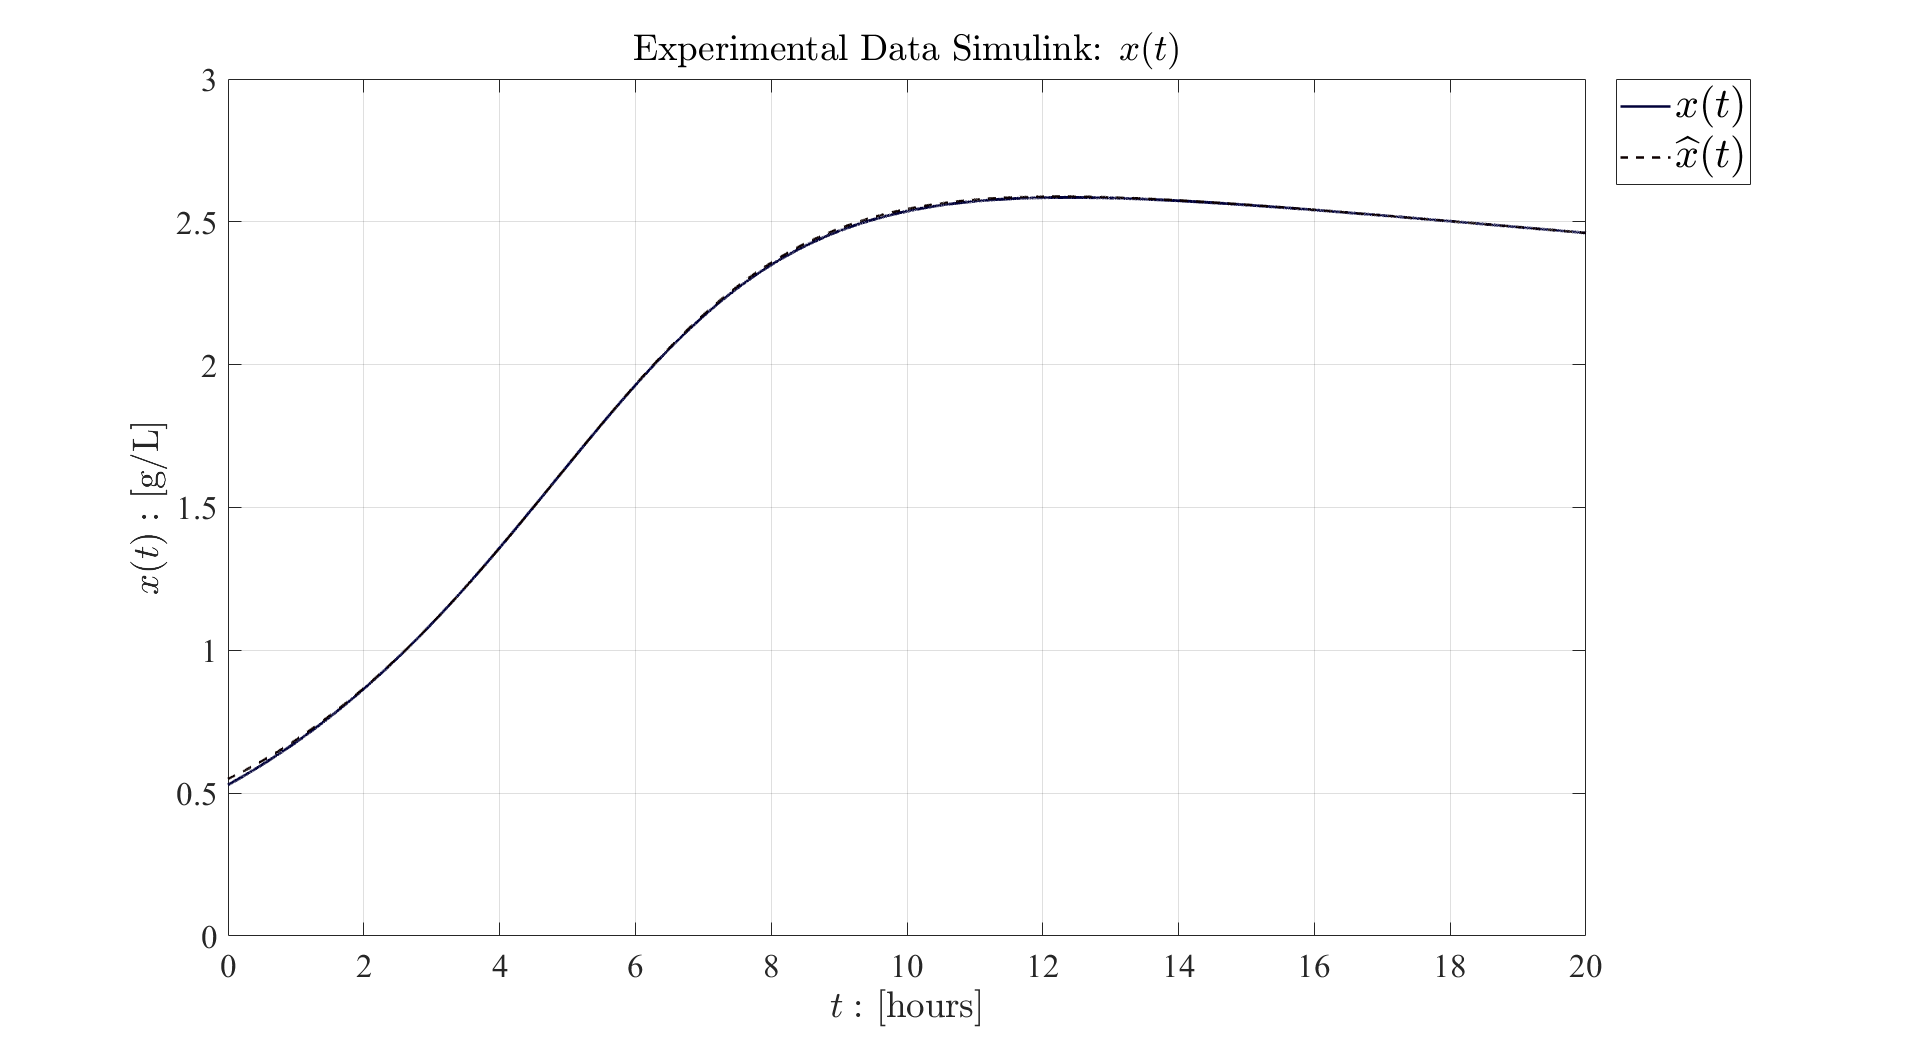


plotData2_x(t, x, xe);

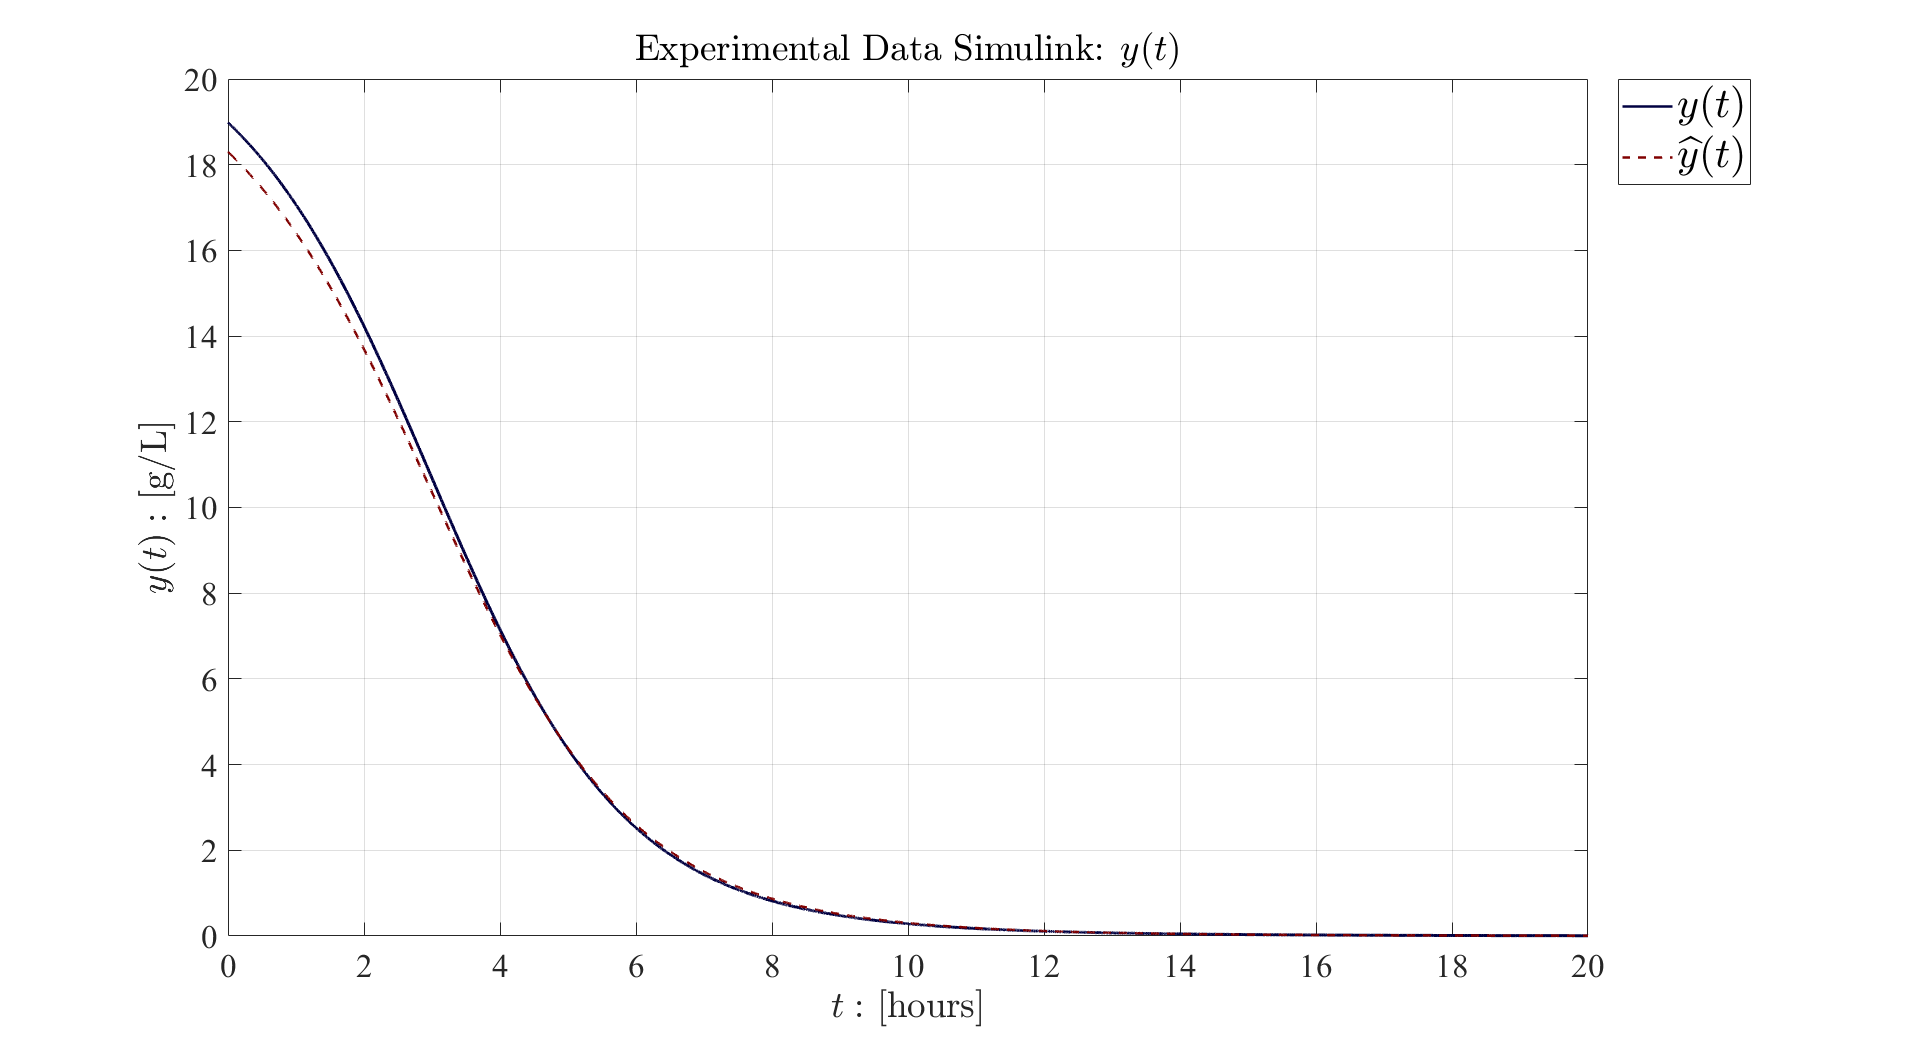

plotData2_y(t, y, ye);

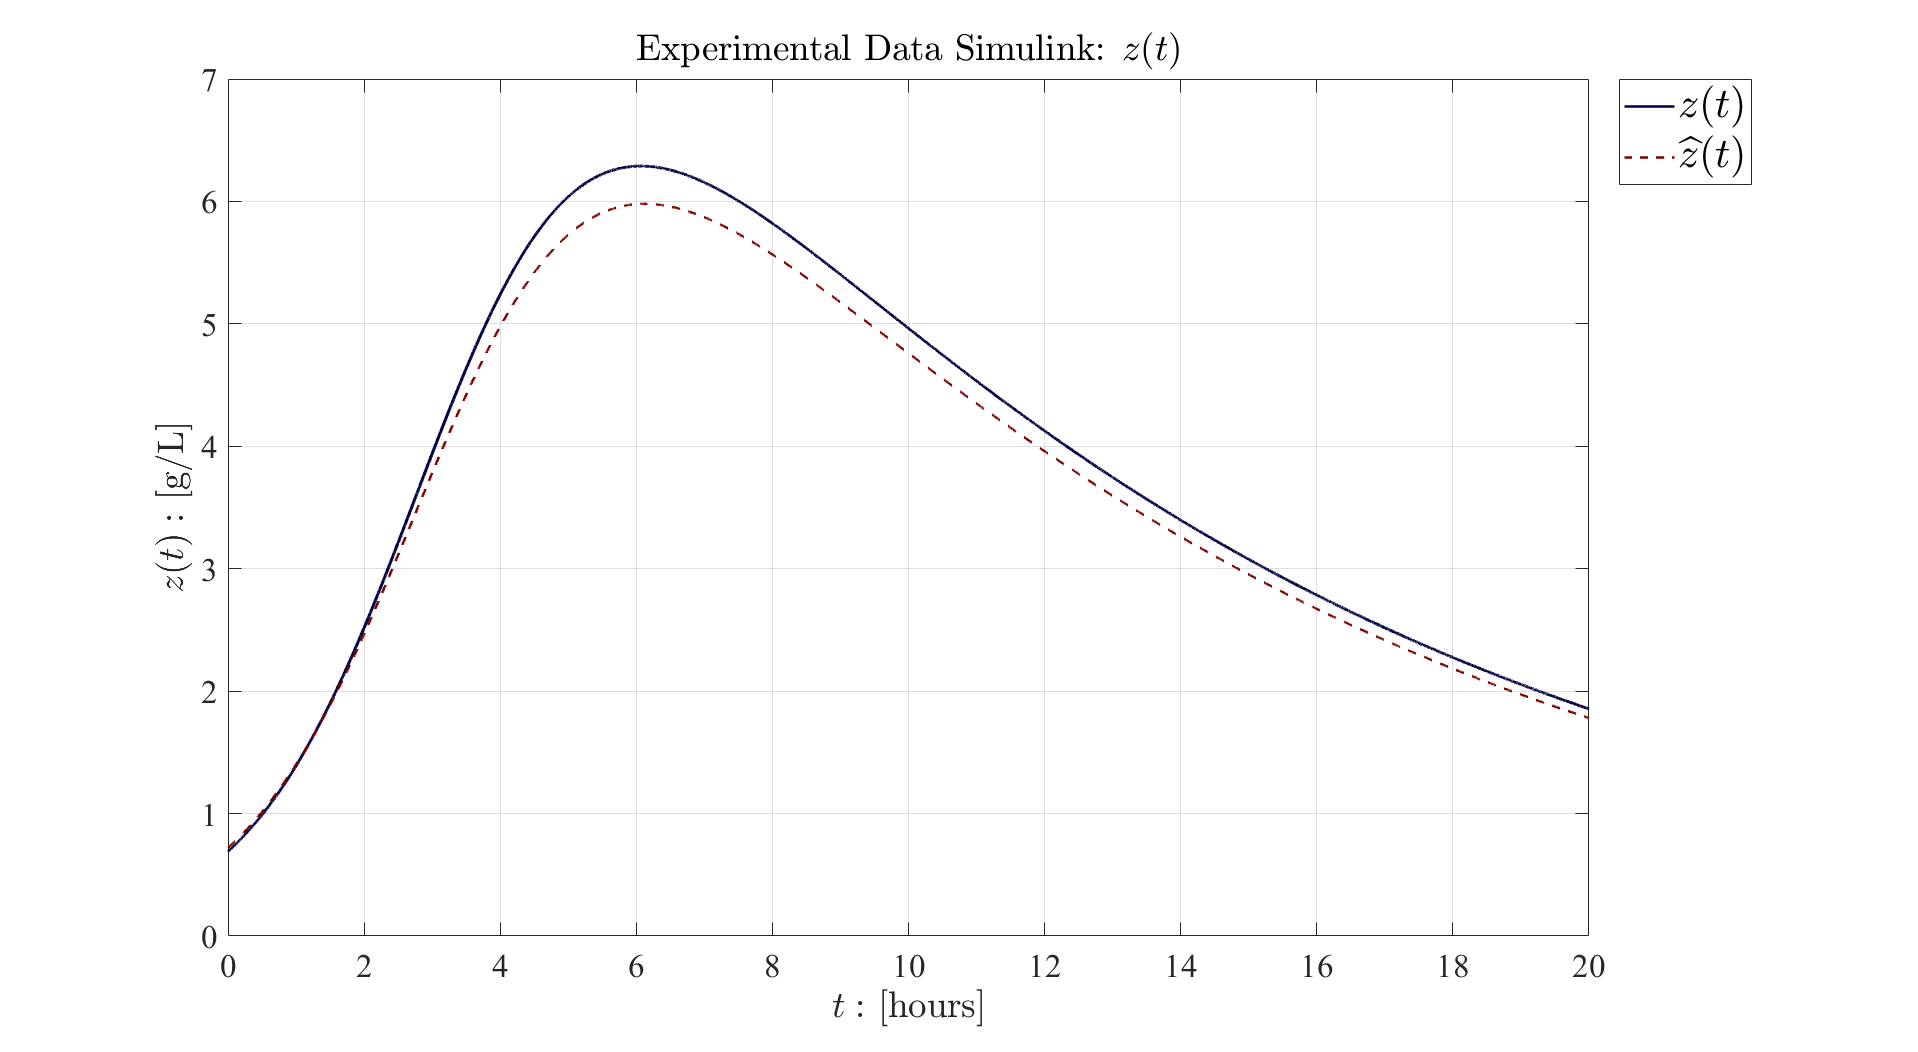

plotData2_z(t, z, ze);

## Funcion

function [x,y,z,xe,ye,ze] = Observer_KM(p,tend,dt,L1,L2,L3)
    
    n = round(tend/dt);
    t = (0:dt:tend)';

    %Dimensiones de los arreglos
    x = zeros(length(t), 1);
    y = zeros(length(t), 1);
    z = zeros(length(t), 1);
    xe = zeros(length(t), 1);
    ye = zeros(length(t), 1); 
    ze = zeros(length(t), 1);
    
    %Parámetros
    p1 = p(1); p2 = p(2); p3 = p(3); p4 = p(4); p5 = p(5);    
    p6 = p(6); p7 = p(7); p8 = p(8); p9 = p(9); p10 = p(10);

    %Condiciones iniciales
    x(1) = 0.5289794; 
    y(1) = 18.9847537 ;
    z(1) = 0.69017179; 
    xe(1) = 0.55;
    ye(1) = 18.3 ;
    ze(1) = 0.72;
    
    function [dx, dy, dz] = f(x,y,z)
        dx = +p1*x*y/(p2+y) -p3*x*z -p4*x;
        dy = -p5*x*y -p6*y*z -p7*y;
        dz = +p8*x*z +p9*y*z -p10*z; 
    end

    function [dx, dy, dz] = observer(x,y,z,xe)
        dx = +p1*x*y/(p2+y) -p3*x*z -p4*x + L1*(x - xe);
        dy = -p5*x*y -p6*y*z -p7*y + L2*(x - xe);
        dz = +p8*x*z +p9*y*z -p10*z + L3*(x - xe); 
    end
    
    for i=1:n
        %Modelo matematico
        %Evaluar en el punto actual 
        [fx, fy, fz] = f(x(i),y(i),z(i));
        %Predecir valores
        xn_b = x(i) + fx*dt;
        yn_b = y(i) + fy*dt;
        zn_b = z(i) + fz*dt;
        % Evaluar las funciones en el punto predicho
        [fnx, fny, fnz] = f(xn_b,yn_b,zn_b);
        x(i+1) = x(i) + dt*(fx + fnx)/2; % Biomasa
        y(i+1) = y(i) + dt*(fy + fny)/2; % Glucosa   
        z(i+1) = z(i) + dt*(fz + fnz)/2; % Etanol 
        
        %Observador
        %Evaluar en el punto actual 
        [fxe, fye, fze] = observer(x(i),ye(i),ze(i),xe(i));
        %Predecir valores
        xen_b = xe(i) + fxe*dt;
        yen_b = ye(i) + fye*dt;
        zen_b = ze(i) + fze*dt;
        % Evaluar las funciones en el punto predicho
        [fenx, feny, fenz] = observer(xen_b,yen_b,zen_b,xe(i));
        xe(i+1) = xe(i) + dt*(fxe + fenx)/2; % Biomasa
        ye(i+1) = ye(i) + dt*(fye + feny)/2; % Glucosa   
        ze(i+1) = ze(i) + dt*(fze + fenz)/2; % Etanol
        
    end
end
%Función del observador

function plotData2(t,x,y,z,xB,yB,zB)
    set(figure(),'color','w')
    set(gcf,'units','centimeters','position',[1,1,15,15])
    FS = 11;

    hold on; box on;
    subplot(3,1,1) %solución x(t)
    plot(t,x,'-','LineWidth',1,'Color',[0,0,0.225])
    hold on; box on;
    plot(t,xB,'--','LineWidth',1,'Color',[0.05,0,0])
    L=legend('$x(t)$','$\widehat{x}(t)$','location','northeast');
    set(L,'interpreter','latex','fontsize',14)
    xlabel('$t:$ [hours]','Interpreter','latex','FontSize',FS)
    ylabel('$x(t):$ [g/L]','Interpreter','latex','FontSize',FS)
    %L = legend('$x(t)$','NumColumns',1); 
    %set(L,'Interpreter','Latex','FontSize',FS,'Location','northeast')
    ylim([0 5]); %xlim([0 210]);
    title('Experimental Data: x(t)')

    set(gca,'FontName','Times New Roman', 'FontSize',FS)
    subplot(3,1,2) %solución y(t)
    hold on; box on;
    plot(t,y,'-','LineWidth',1,'Color',[0,0,0.254])
    hold on; box on;
    plot(t,yB,'--','LineWidth',1,'Color',[0.5,0,0])
    L=legend('$y(t)$','$\widehat{y}(t)$','location','northeast');
    set(L,'interpreter','latex','fontsize',14)
    xlabel('$t:$ [hours]','Interpreter','latex','FontSize',FS)
    ylabel('$y(t):$ [g/L]','Interpreter','latex','FontSize',FS)
    %L = legend('$y(t)$','NumColumns',1); 
    %set(L,'Interpreter','Latex','FontSize',FS,'Location','northeast')
    ylim([0 20]); %xlim([0 210]);
    set(gca,'FontName','Times New Roman', 'FontSize',FS)
    title('Experimental Data: y(t)')

    set(gca,'FontName','Times New Roman', 'FontSize',FS)
    subplot(3,1,3) %solución z(t)
    hold on; box on;
    plot(t,z,'-','LineWidth',1,'Color',[0,0,0.254])
    hold on; box on;
    plot(t,zB,'--','LineWidth',1,'Color',[0.5,0,0])
    L=legend('$z(t)$','$\widehat{z}(t)$','location','northeast');
    set(L,'interpreter','latex','fontsize',14)
    xlabel('$t:$ [hours]','Interpreter','latex','FontSize',FS)
    ylabel('$z(t):$ [g/L]','Interpreter','latex','FontSize',FS)
    %L = legend('$y(t)$','NumColumns',1); 
    %set(L,'Interpreter','Latex','FontSize',FS,'Location','northeast')
    ylim([0 10]); %xlim([0 210]);
    set(gca,'FontName','Times New Roman', 'FontSize',FS)
    title('Experimental Data: y(t)')
    exportgraphics(gcf,'ExperimentalData.pdf','ContentType','vector')
end

function plotData2_x(t, x, xB)
    figure('Color', 'w', 'Units', 'centimeters', 'Position', [1, 1, 55, 30]);
    FS = 20;

    plot(t, x, '-', 'LineWidth', 1.5, 'Color', [0, 0, 0.225]);
    hold on;
    plot(t, xB, '--', 'LineWidth', 1.5, 'Color', [0.05, 0, 0]);
    grid on;
    legend('$x(t)$', '$\widehat{x}(t)$', 'Interpreter', 'latex', 'FontSize', 25, 'Location', 'northeastoutside');
    xlabel('$t:$ [hours]', 'Interpreter', 'latex', 'FontSize', FS);
    ylabel('$x(t):$ [g/L]', 'Interpreter', 'latex', 'FontSize', FS);
    ylim([0 3]);
    xlim([0 20]); % Se establece el límite de t a 20
    title('Experimental Data Simulink: $x(t)$', 'Interpreter', 'latex', 'FontSize', FS);
    set(gca, 'FontName', 'Times New Roman', 'FontSize', FS);
    exportgraphics(gcf,'ExperimentalData_x3_S.pdf','ContentType','vector')
end
function plotData2_y(t, y, yB)
    figure('Color', 'w', 'Units', 'centimeters', 'Position', [1, 1, 55, 30]);
    FS = 20;

    plot(t, y, '-', 'LineWidth', 1.5, 'Color', [0, 0, 0.254]);
    hold on;
    plot(t, yB, '--', 'LineWidth', 1.5, 'Color', [0.5, 0, 0]);
    grid on;
    legend('$y(t)$', '$\widehat{y}(t)$', 'Interpreter', 'latex', 'FontSize', 25, 'Location', 'northeastoutside');
    xlabel('$t:$ [hours]', 'Interpreter', 'latex', 'FontSize', FS);
    ylabel('$y(t):$ [g/L]', 'Interpreter', 'latex', 'FontSize', FS);
    ylim([0 20]);
    title('Experimental Data Simulink: $y(t)$', 'Interpreter', 'latex', 'FontSize', FS);
    set(gca, 'FontName', 'Times New Roman', 'FontSize', FS);
    exportgraphics(gcf,'ExperimentalData_y3_S.pdf','ContentType','vector')
end

function plotData2_z(t, z, zB)
    figure('Color', 'w', 'Units', 'centimeters', 'Position', [1, 1, 55, 30]);
    FS = 20;

    plot(t, z, '-', 'LineWidth', 1.5, 'Color', [0, 0, 0.254]);
    hold on;
    plot(t, zB, '--', 'LineWidth', 1.5, 'Color', [0.5, 0, 0]);
    grid on;
    legend('$z(t)$', '$\widehat{z}(t)$', 'Interpreter', 'latex', 'FontSize', 25, 'Location', 'northeastoutside');
    xlabel('$t:$ [hours]', 'Interpreter', 'latex', 'FontSize', FS);
    ylabel('$z(t):$ [g/L]', 'Interpreter', 'latex', 'FontSize', FS);
    ylim([0 7]);
    title('Experimental Data Simulink: $z(t)$', 'Interpreter', 'latex', 'FontSize', FS);
    set(gca, 'FontName', 'Times New Roman', 'FontSize', FS);
    exportgraphics(gcf,'ExperimentalData_z3_S.pdf','ContentType','vector')
end
